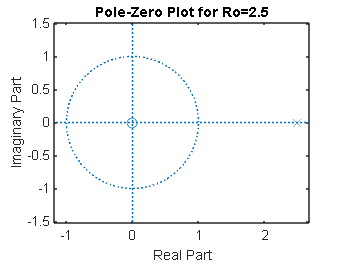

%Q1.1
R0 =2.5; % Replace this with your specific R0 value
num_1 = 1;
den_1 = [1, -R0];

zplane(num_1, den_1);
title('Pole-Zero Plot for Ro=2.5')

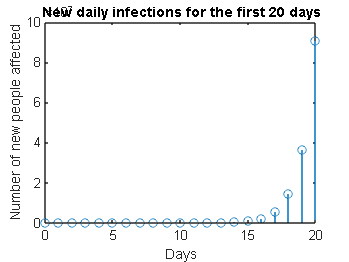

%Q1.5
n=0:1:20;
R=2.5;
y=inline('(2.5).^n','n');
stem(n,y(n))
title('New daily infections for the first 20 days');
xlabel('Days')
ylabel('Number of new people affected')


day_to_reach_million = log(1000000)/log(2.5)

day_to_reach_million = 15.0776

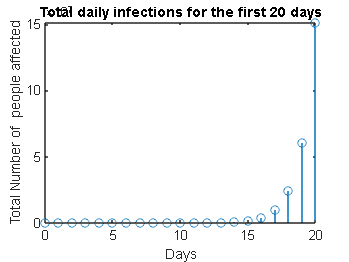

num=[1];
den=[1 -1];
h=filter(num,den,y(n));
stem(n,h)
title('Total daily infections for the first 20 days');
xlabel('Days')
ylabel('Total Number of  people affected')

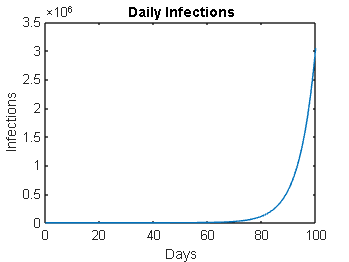

%Q2
% Define the filter coefficients
a = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];

% Number of days
n = 100;

% Initialize input signal (Kronecker delta)
input_signal = [1; zeros(n,1)];

% Initialize arrays to store daily infections and cumulative infections
daily_infections = filter(1, [1, -a], input_signal);
cumulative_infections = filter(num,den,daily_infections);

% Plot the daily infections
figure;
plot(0:n, daily_infections);
title('Daily Infections');
xlabel('Days');
ylabel('Infections');

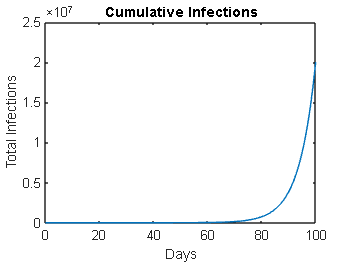


% Plot the cumulative infections
figure;
plot(0:n, cumulative_infections);
title('Cumulative Infections ');
xlabel('Days');
ylabel('Total Infections');


% Find the day when daily infections reach 1 million
day_to_reach_million_1 = find(daily_infections >= 1e6, 1)-1

day_to_reach_million_1 = 94

cumulative_infections(n+1)

ans = 2.0044e+07

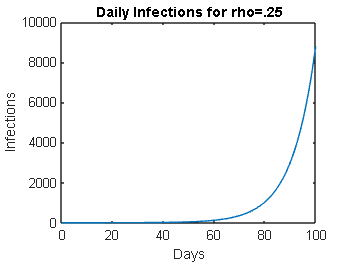

%Q3.1
% Define the filter coefficients
a = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
b_1=(1-0.25).*a;
% Number of days
n = 100;

% Initialize input signal (Kronecker delta)
input_signal = [1; zeros(n,1)];

% Initialize arrays to store daily infections and cumulative infections
daily_infections_1 = filter(1, [1, -b_1], input_signal);
cumulative_infections_1 = filter(num,den,daily_infections_1);

% Plot the daily infections
figure;
plot(0:n, daily_infections_1);
title('Daily Infections for rho=.25');
xlabel('Days');
ylabel('Infections');


cumulative_infections_1(n+1) 

ans = 8.6548e+04

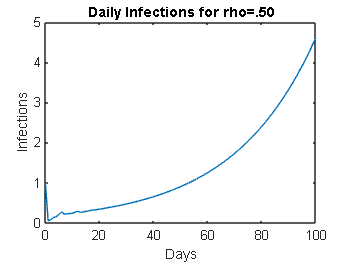

%Q3.2
% Define the filter coefficients
a = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
b_2=(1-0.50).*a;
% Number of days
n = 100;

% Initialize input signal (Kronecker delta)
input_signal = [1; zeros(n,1)];

% Initialize arrays to store daily infections and cumulative infections
daily_infections_2 = filter(1, [1, -b_2], input_signal);
cumulative_infections_2 = filter(num,den,daily_infections_2);

% Plot the daily infections
figure;
plot(0:n, daily_infections_2);
title('Daily Infections for rho=.50');
xlabel('Days');
ylabel('Infections');

cumulative_infections_2(n+1)

ans = 138.5073

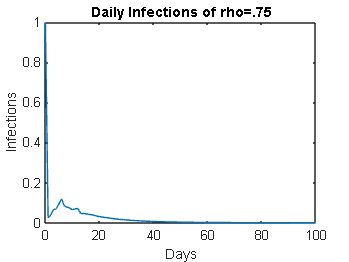

%Q3.3
% Define the filter coefficients
a = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
b_3=(1-0.75).*a;
% Number of days
n = 100;

% Initialize input signal (Kronecker delta)
input_signal = [1; zeros(n,1)];

% Initialize arrays to store daily infections and cumulative infections
daily_infections_3 = filter(1, [1, -b_3], input_signal);
cumulative_infections_3 = filter(num,den,daily_infections_3);

% Plot the daily infections
figure;
plot(0:n, daily_infections_3);
title('Daily Infections of rho=.75');
xlabel('Days');
ylabel('Infections');

cumulative_infections_3(n+1)

ans = 2.5310

% Problem 4

% Part(1)
Ro = 1.15;
K = 10^6;
n = 1:100;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) % Total infections in 100 days

Total_infections2 = 1.6928e+07

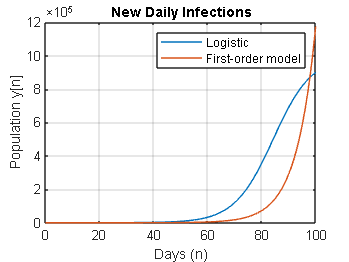


days = 0:100;
Ro = 1.15;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
figure;
plot(n,logistic)
hold on 
plot(days,populationx)
hold off
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on
legend("Logistic","First-order model")




% Part(2)
filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value

Global_maximum = 3.4918e+04

Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value

Value_n = 85

Zero_crossing = n(round(filter_2) == 94) % Inflection point

Zero_crossing = 85

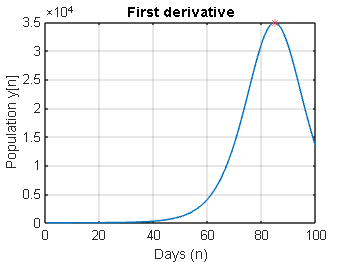


figure;
plot(n,filter_1,n(Value_n),filter_1(Value_n),'r*')
title("First derivative")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

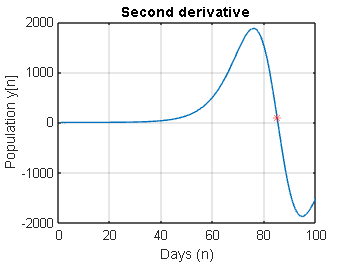


figure;
plot(n,filter_2,n(Zero_crossing),filter_2(Zero_crossing),'r*')
title("Second derivative ")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on